# Comparing NPP and Sea Ice Concentration Data

## Load data

clearvars
close all

desktop = 0;
laptop=1;
if desktop
    addpath(genpath('C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg'))
    cd 'C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Projects\carbonuptakeinwg\data\processed' % desktop
    addpath(genpath('C:\Users\Clara Douglas\OneDrive - University of Southampton\PhD\Matlab Add-ins'));
elseif laptop
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG'))
    cd 'C:\Users\ccd1n18\Documents\Projects\CarbonUptakeInWG\data\processed' % laptop
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\m_map'));
    addpath(genpath('C:\Users\ccd1n18\Documents\Projects\SetCMap'));
end

%algorithm={'cafe','cbpm','eppley','vgpm'};
algorithm={'cafe'};
setup.checkregions=true;
setup.plotfigures=true;
setup.startyear=2002;
setup.endyear=2020;
setup.monthly=false;
setup.eightday=true;
setup.yearrange=setup.startyear:1:setup.endyear; setup.yearrange=setup.yearrange';
setup.yearrange0320=setup.yearrange(2:end,:);
continue_run=0;

load('ProcessedData_8day_Feb22.mat')
load('SeaIce8day_Apr22_wWAP.mat')

## Compare 

Calculate the area of ice free water/ice covered water represented by each satellite

i.e. 

Sea Ice: Area of Region - SeaIce.REGION.IceFree_Extent(or ice_free_area) = Extent (or Area) of water that is ice covered ==> **SeaIce.REGION.SIExtent or SeaIce.REGION.ice_covered_area**

NPP data: Area of Region - OceanProd_8day.cafe.REGION.area_8day_km2 = **Area of water not visible in the NPP data** 

or compare 

**SeaIce.REGION.IceFree_Extent or SeaIce.REGION.ice_free_area **to** OceanProd_8day.cafe.REGION.area_8day_m2(or km2)**

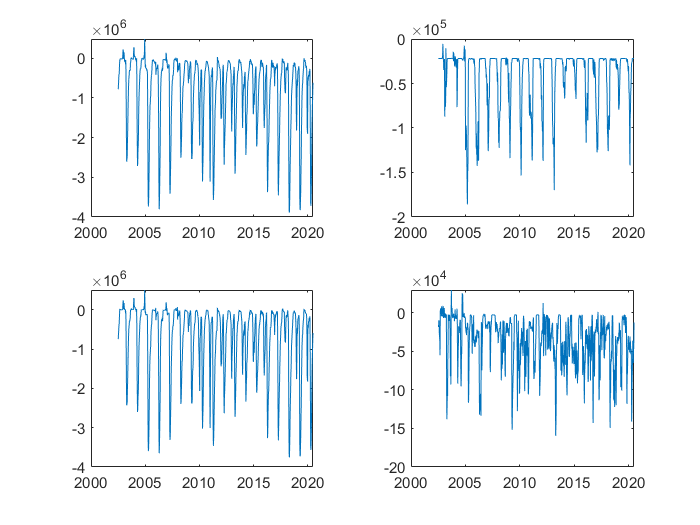

region_sublist={'Weddell','Shelf','Open','WAP'}; %
% 849:end NPP data doesn't have corresponding sea ice data (goes into 2021)
% 829:end for both to remove later than 2020 austral year

for rix = 1:length(region_sublist)
CoverageDiff_extent.(region_sublist{rix})=OceanProd_8day.cafe.(region_sublist{rix}).area_8day_km2(1:828)-SeaIce.(region_sublist{rix}).IceFree_Extent(1:828);
CoverageDiff_area.(region_sublist{rix})=OceanProd_8day.cafe.(region_sublist{rix}).area_8day_km2(1:828)-SeaIce.(region_sublist{rix}).IceFree_Extent(1:828);
end

figure;
tiledlayout('flow')
for rix = 1:length(region_sublist)
nexttile
plot(timedec8dayice(1:828),CoverageDiff_extent.(region_sublist{rix}));
end

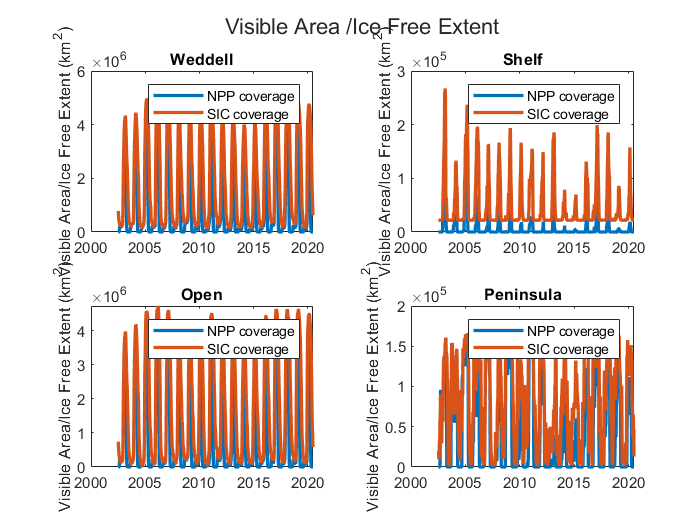


figure;
tiledlayout('flow')
for rix = 1:length(region_sublist)
nexttile
plot(timedec8dayice(1:828),OceanProd_8day.cafe.(region_sublist{rix}).area_8day_km2(1:828),'LineWidth',2);
hold on
plot(timedec8dayice(1:828),SeaIce.(region_sublist{rix}).IceFree_Extent(1:828),'LineWidth',2);
legend('NPP coverage','SIC coverage')
if rix==4
    title('Peninsula')
else
    title(region_sublist{rix})
end
sgtitle('Visible Area /Ice Free Extent')
ylabel('Visible Area/Ice Free Extent (km^2)')
end

% specific years check
yearcheck=[2010,2014,2016,2018,2019]
        x_months= {'J','A','S','O','N','D','J','F','M','A','M','J'};
for rix = 1:length(region_sublist)
    figure;
    tiledlayout('flow')
    for yix = yearcheck
        findyearaus=find(timedec8dayice_start>yix-0.5 & timedec8dayice_start<yix+0.5);
        nexttile
        plot(CoverageDiff_extent.(region_sublist{rix})(findyearaus),'LineWidth',2);
        title(yix)
        sgtitle(region_sublist{rix})
        set(gca,'xtick',[1 5 8 12 16 20 24 28 31 35 39 43],'xticklabel',x_months,'FontSize',14)
    end
end